# Plan Mobile Robot Paths Using RRT 4-9

This example shows how to use the rapidly exploring random tree (RRT) algorithm to plan a path for a vehicle through a known map. Special vehicle constraints are also applied with a custom state space. You can tune your own planner with custom state space and path validation objects for any navigation application. 

load("data34_12F_0407walk.mat")

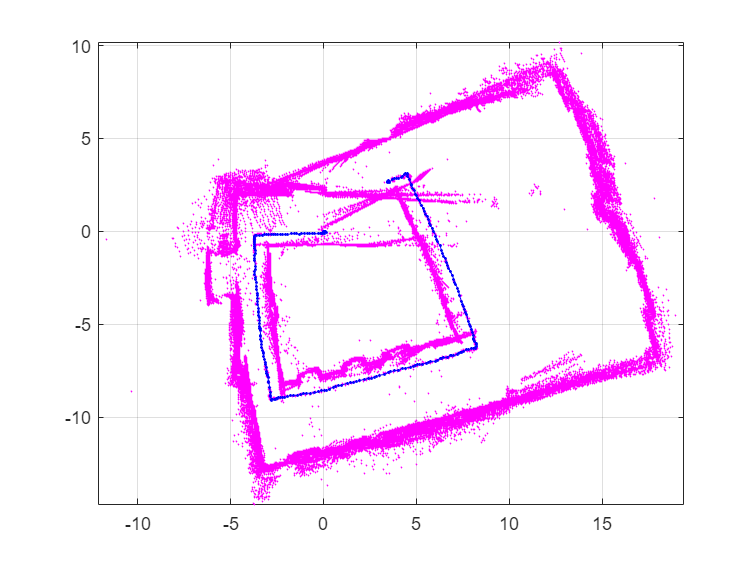

scans = scans(1:2:end);

maxRange = 12; % meters
resolution = 20; % cells per meter

slamObj = lidarSLAM(resolution,maxRange);
slamObj.LoopClosureThreshold = 360;
slamObj.LoopClosureSearchRadius = 8;

for i = 1:numel(scans)

    addScan(slamObj,scans{i});

    if rem(i,10) == 0
        show(slamObj);
    end
end

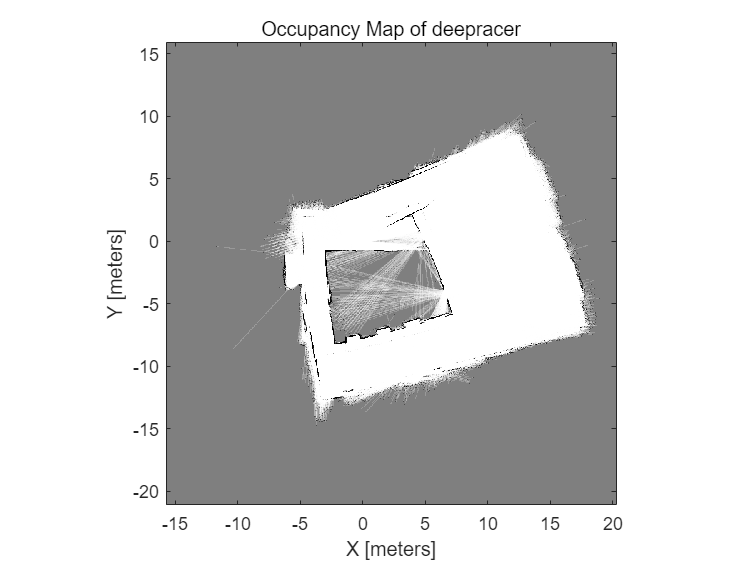


[scansSLAM,poses] = scansAndPoses(slamObj);
deepracerMap = buildMap(scansSLAM,poses,resolution,maxRange);
figure
show(deepracerMap)
title('Occupancy Map of deepracer')

## Load Occupancy Map

Load an existing occupancy map of a small office space. Plot the start and goal poses of the vehicle on top of the map.

%load("office_area_gridmap.mat","occGrid")
load("deepracermap.mat","deepracerMap")


occGrid=deepracerMap;
%아 멍청했다 그냥 map에도 넣어줄걸
map= deepracerMap

map =   occupancyMap - 속성 있음:

   mapLayer Properties
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
                LayerName: 'probabilityLayer'
                 DataType: 'double'
             DefaultValue: 0.5000
      GridLocationInWorld: [-17.3695 -22.4887]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [-17.3695 -22.4887]
               Resolution: 20
                 GridSize: [700 640]
             XLocalLimits: [0 32]
             YLocalLimits: [0 35]
             XWorldLimits: [-17.3695 14.6305]
             YWorldLimits: [-22.4887 12.5113]


% 2D_Grid Map의 좌측상단에 있는'저장' 버튼을 이용해 작업경로에 fig 파일로 저장해야 함

fig = openfig('deepracer.fig','visible'); % fig 파일 지정

[xi,yi] = getpts(fig); % 해당 fig 파일을 불러옴 
start = [xi,yi, -pi]; % 해당 fig 파일에서 지점을 클릭 후 Enter를 누르면 point 지정 완료

[xj,yj] = getpts(fig); % 해당 fig 파일을 불러옴
goal = [xj,yj, 0];  % 해당 fig 파일에서 지점을 클릭 후 Enter를 누르면 point 지정 완료


disp(start); % 설정한 start_point의 좌표값 출력

   -4.0328    0.5535   -3.1416



disp(goal); % 설정한 end_point의 좌표값 출력

   -3.2565    0.5966         0



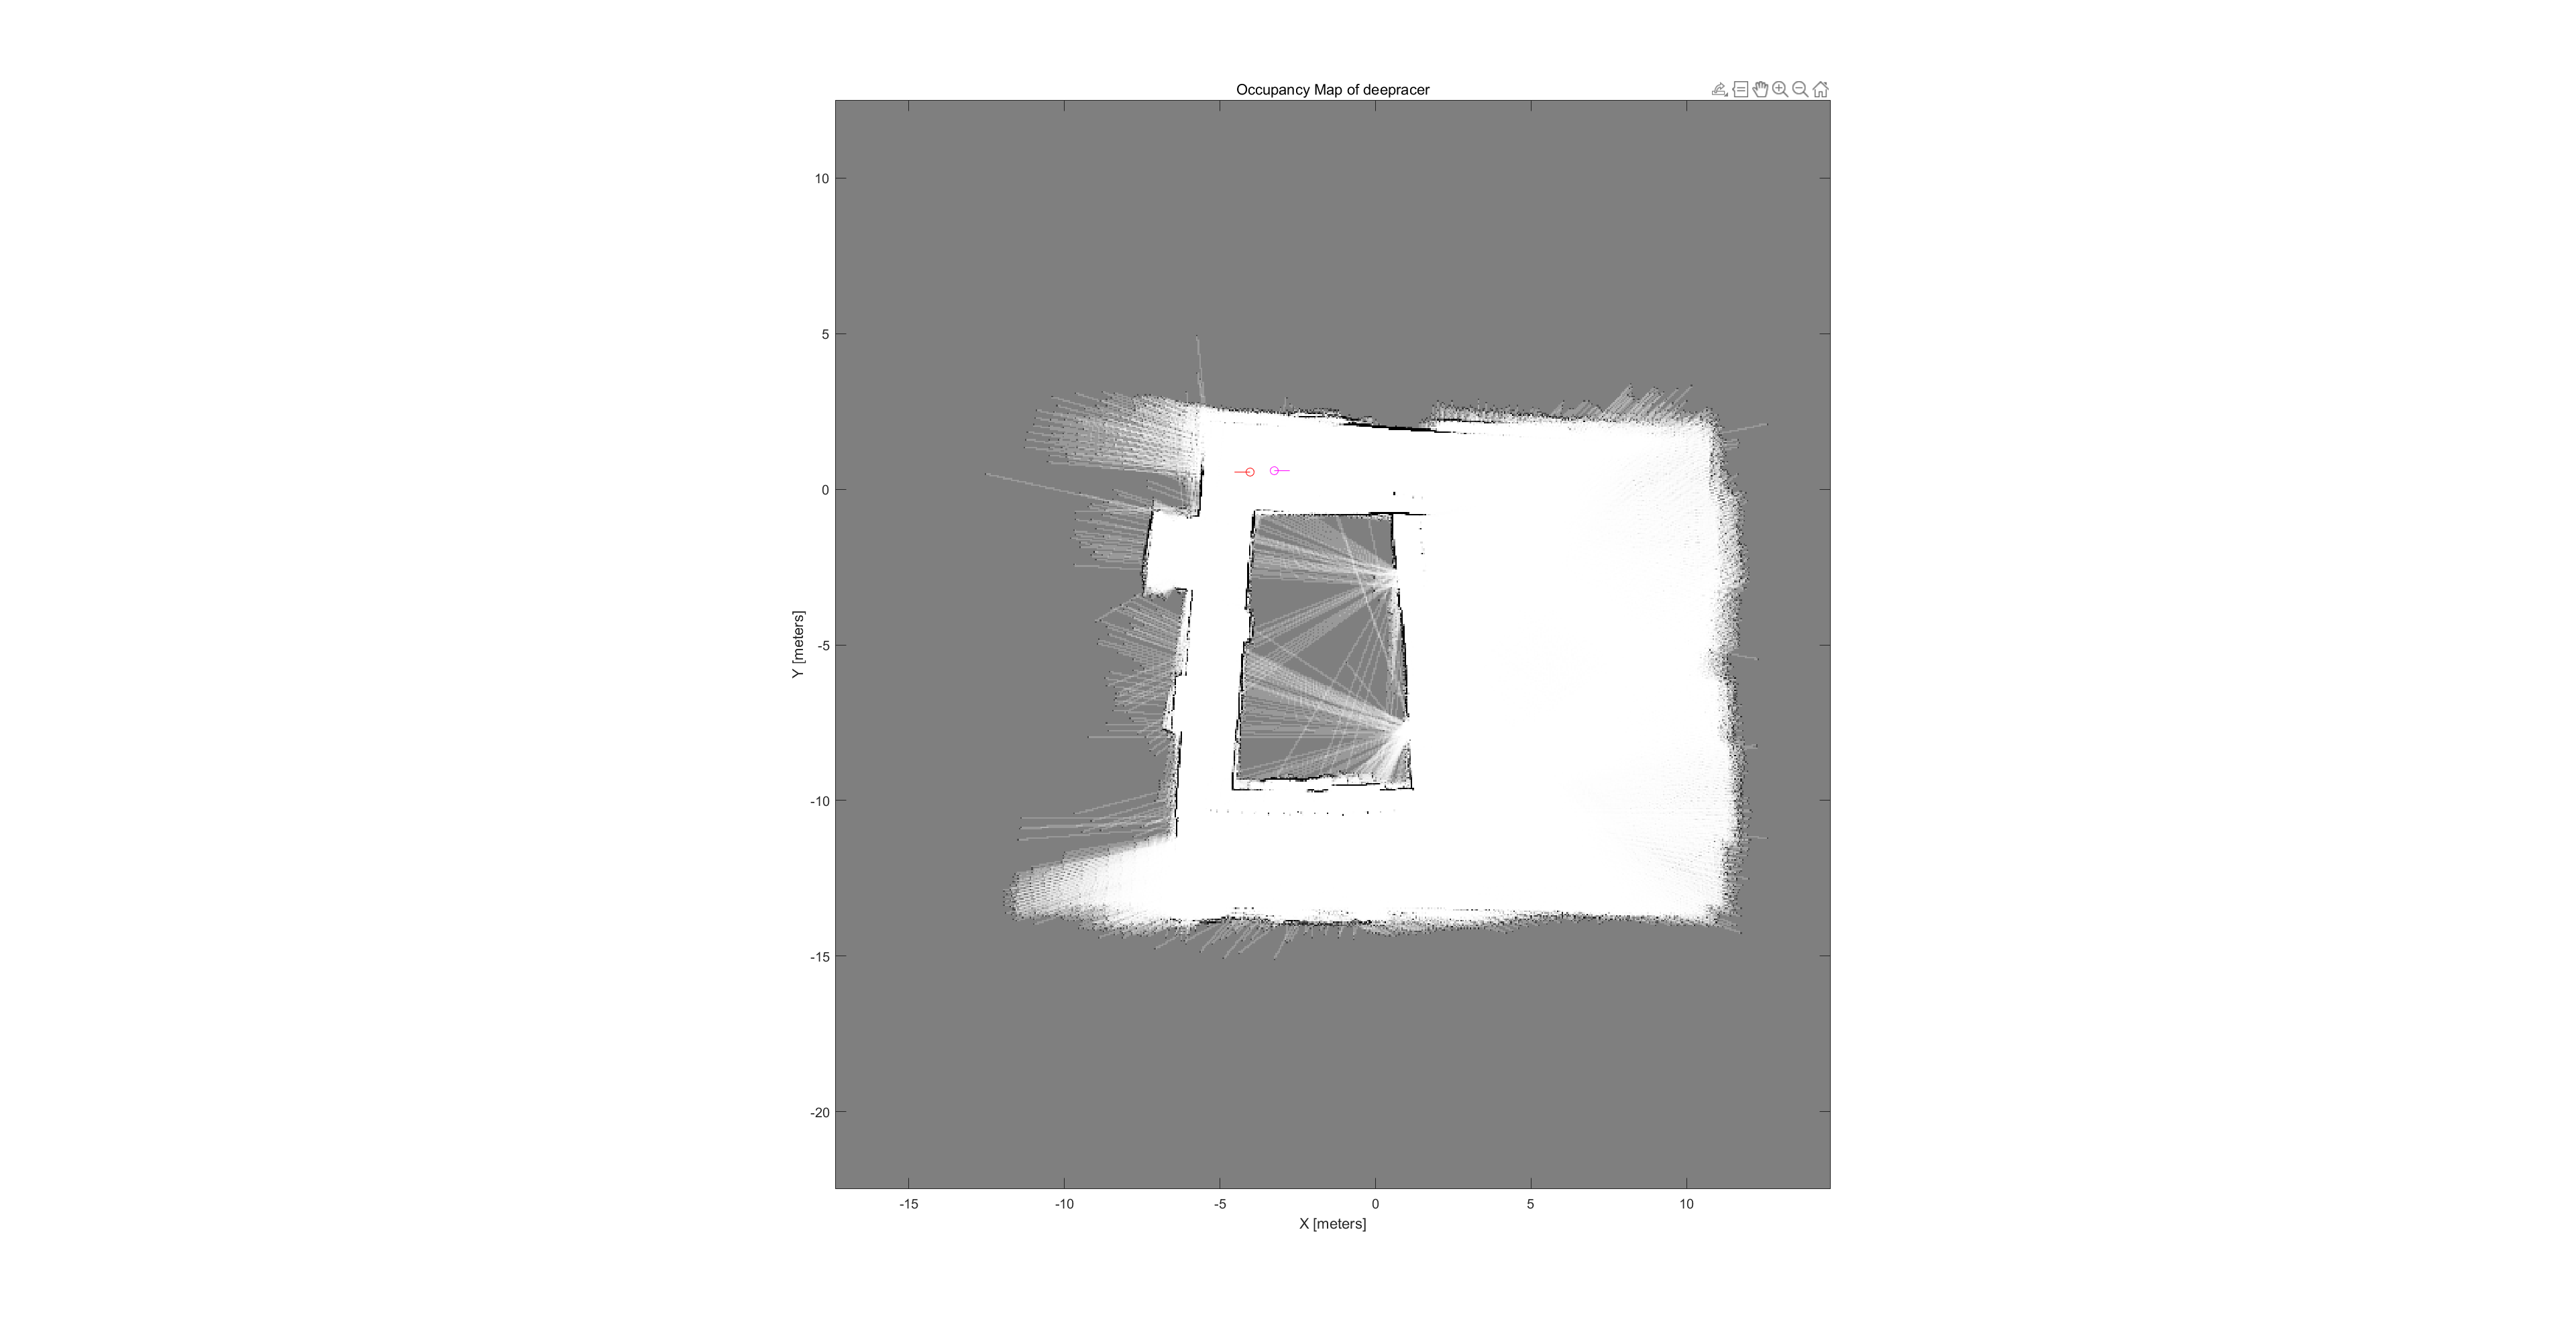

 

% Show start and goal positions of robot.
hold on
plot(start(1),start(2),'ro')
plot(goal(1),goal(2),'mo')

% Show start and goal headings.
r = 0.5;
plot([start(1),start(1) + r*cos(start(3))],[start(2),start(2) + r*sin(start(3))],'r-')
plot([goal(1),goal(1) + r*cos(goal(3))],[goal(2),goal(2) + r*sin(goal(3))],'m-')
hold off

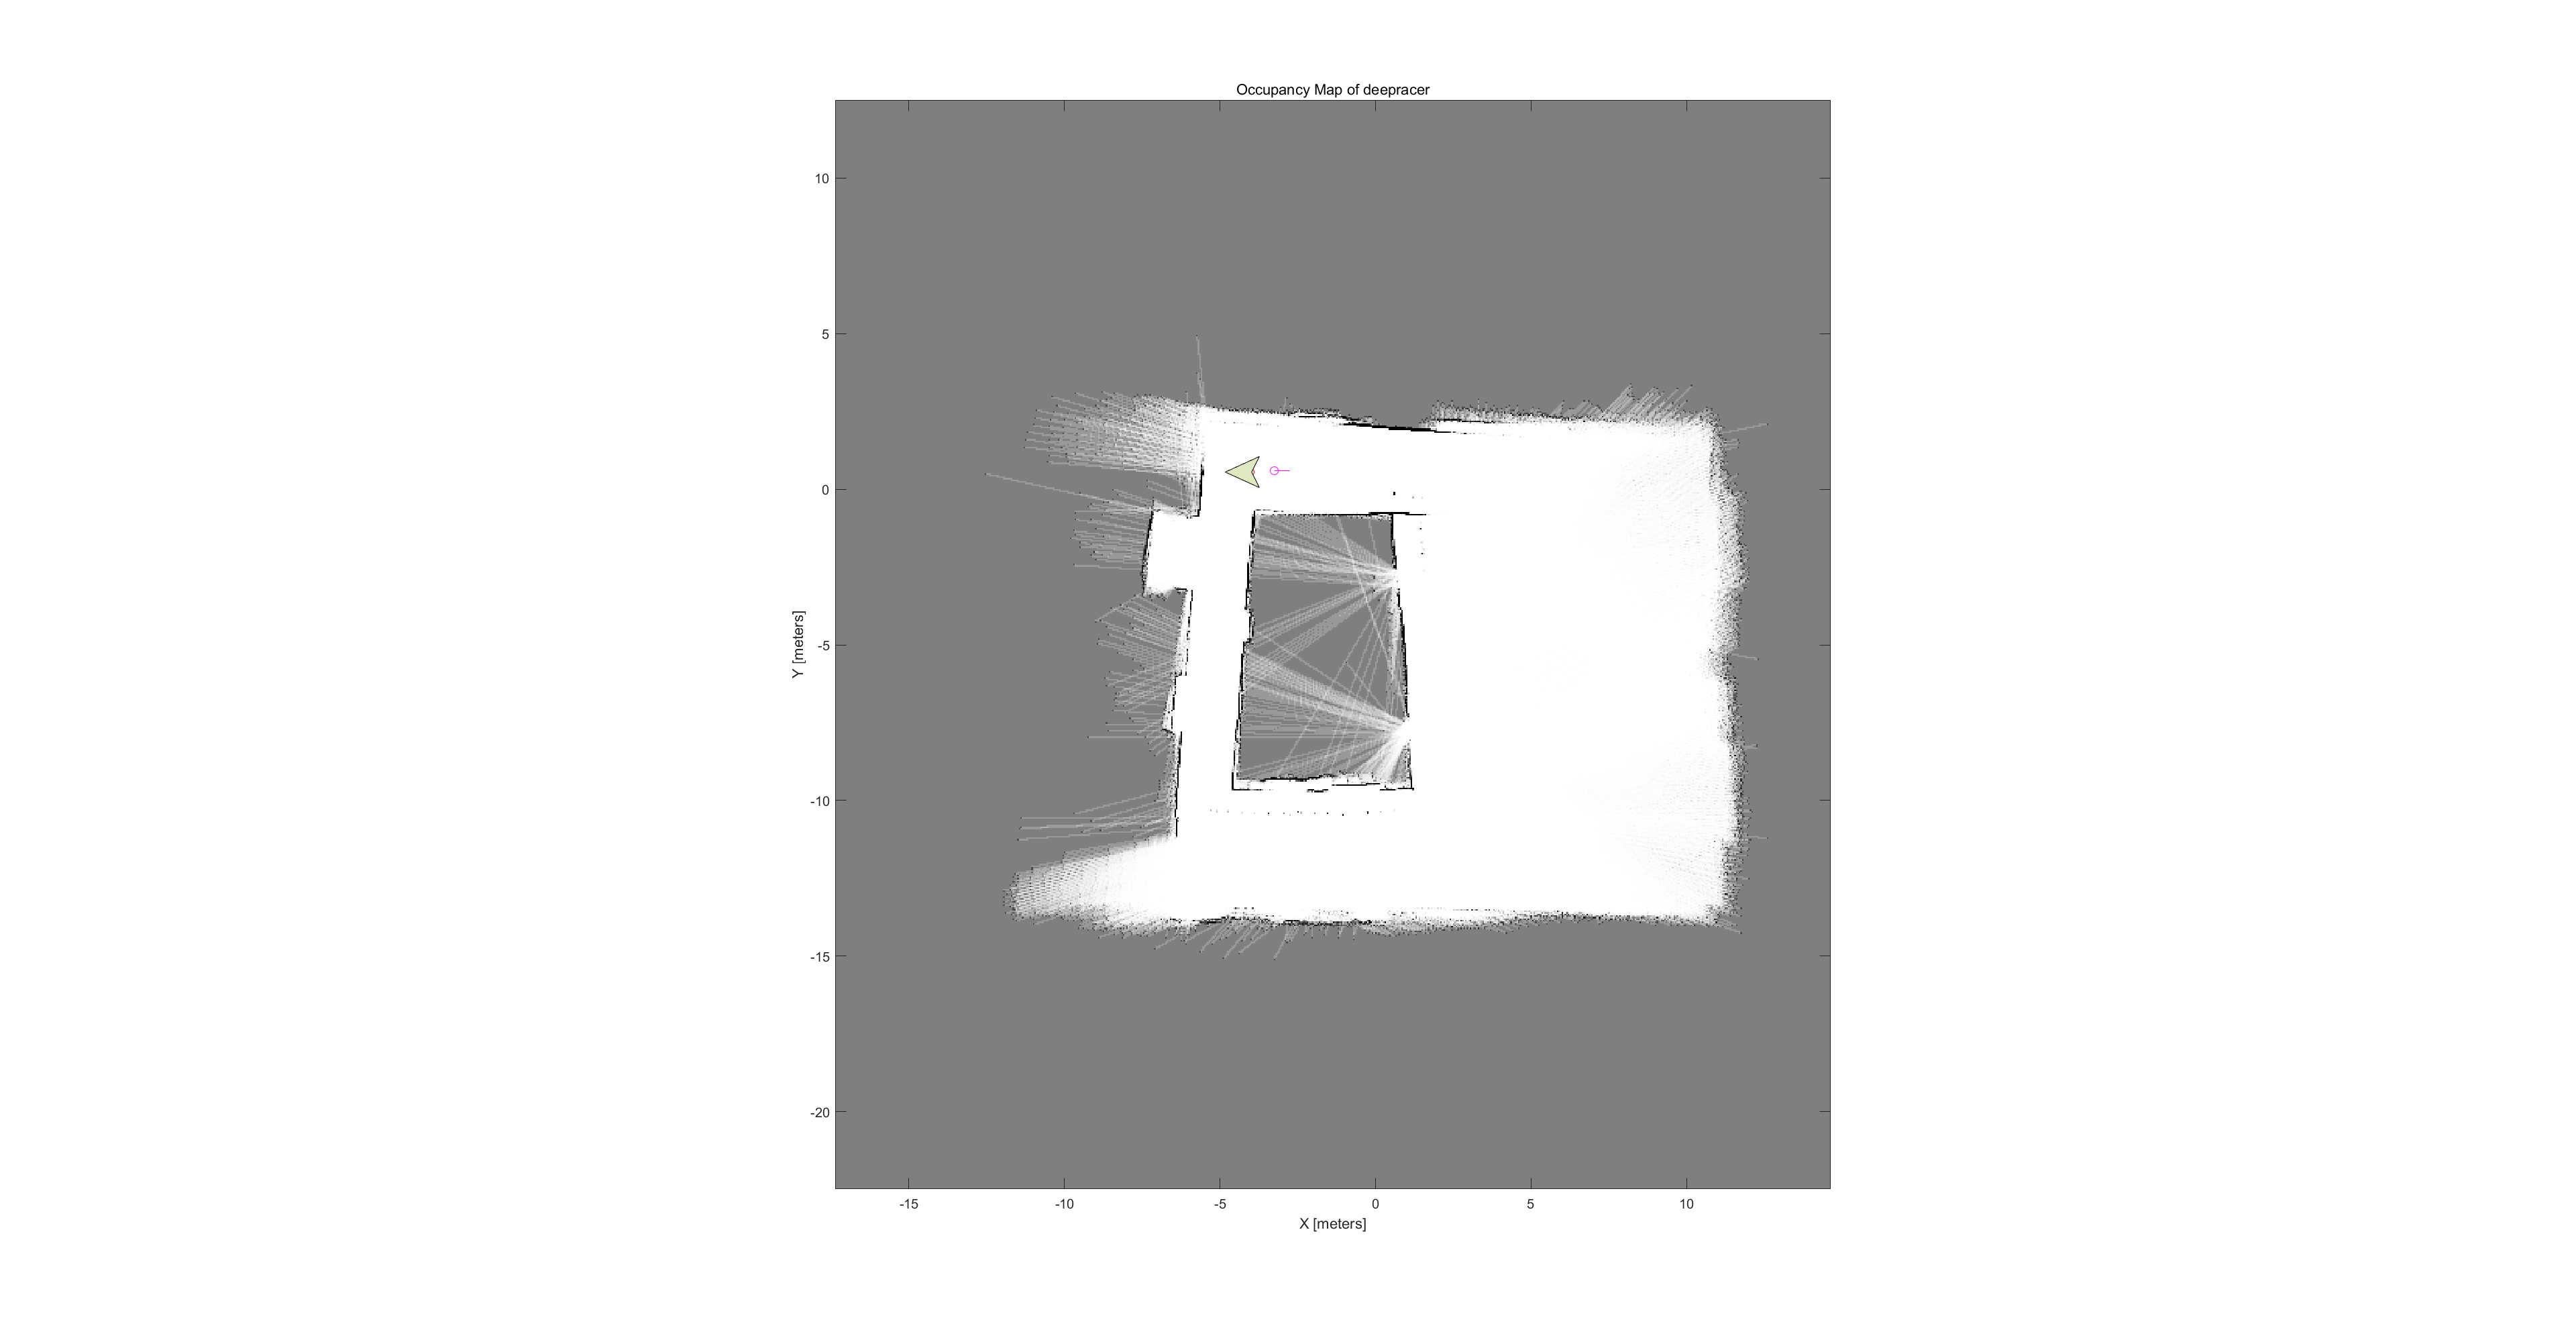

% Add AGV to the map
%pose = [5 40 0];
pose = start;
helperPlotRobot(gca,pose);

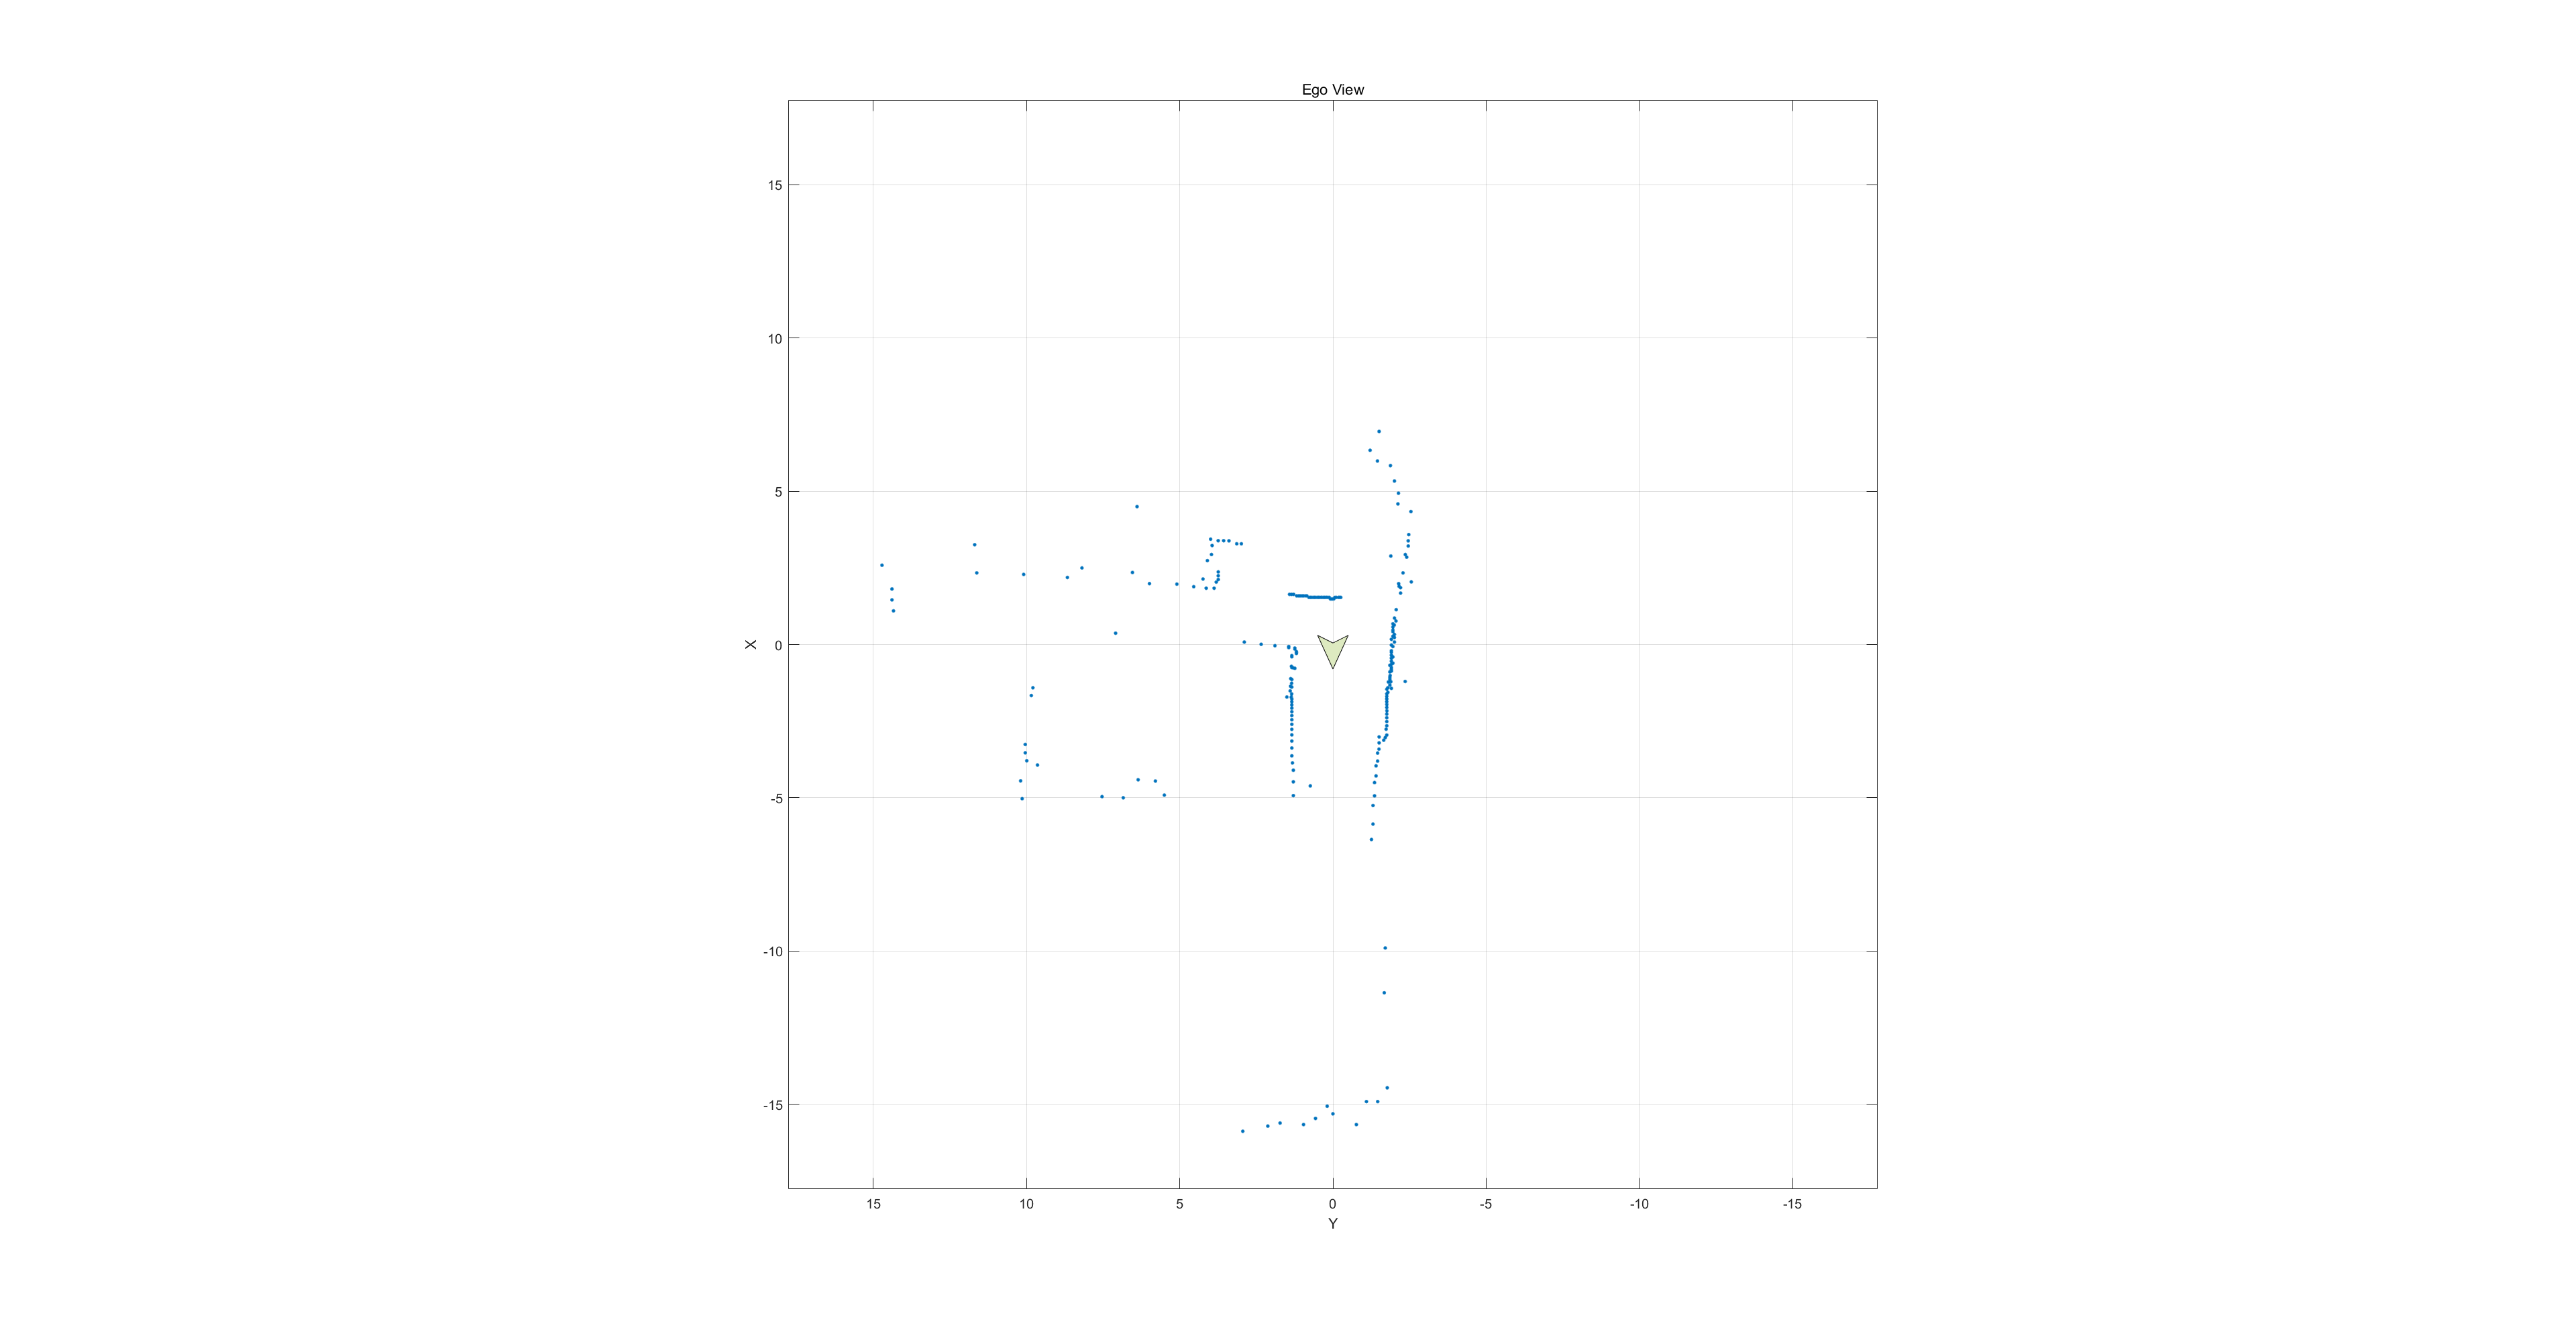


Vehiclepose = pose;


lidar = rangeSensor;
%lidar.HorizontalAngle = [-pi/2 pi/2];

[ranges,angles] = lidar(Vehiclepose,map);


scantest = lidarScan(ranges,angles);
plot(scantest)
title('Ego View')
helperPlotRobot(gca,[0 0 Vehiclepose(3)]);
%hold off

doc rangeSensor

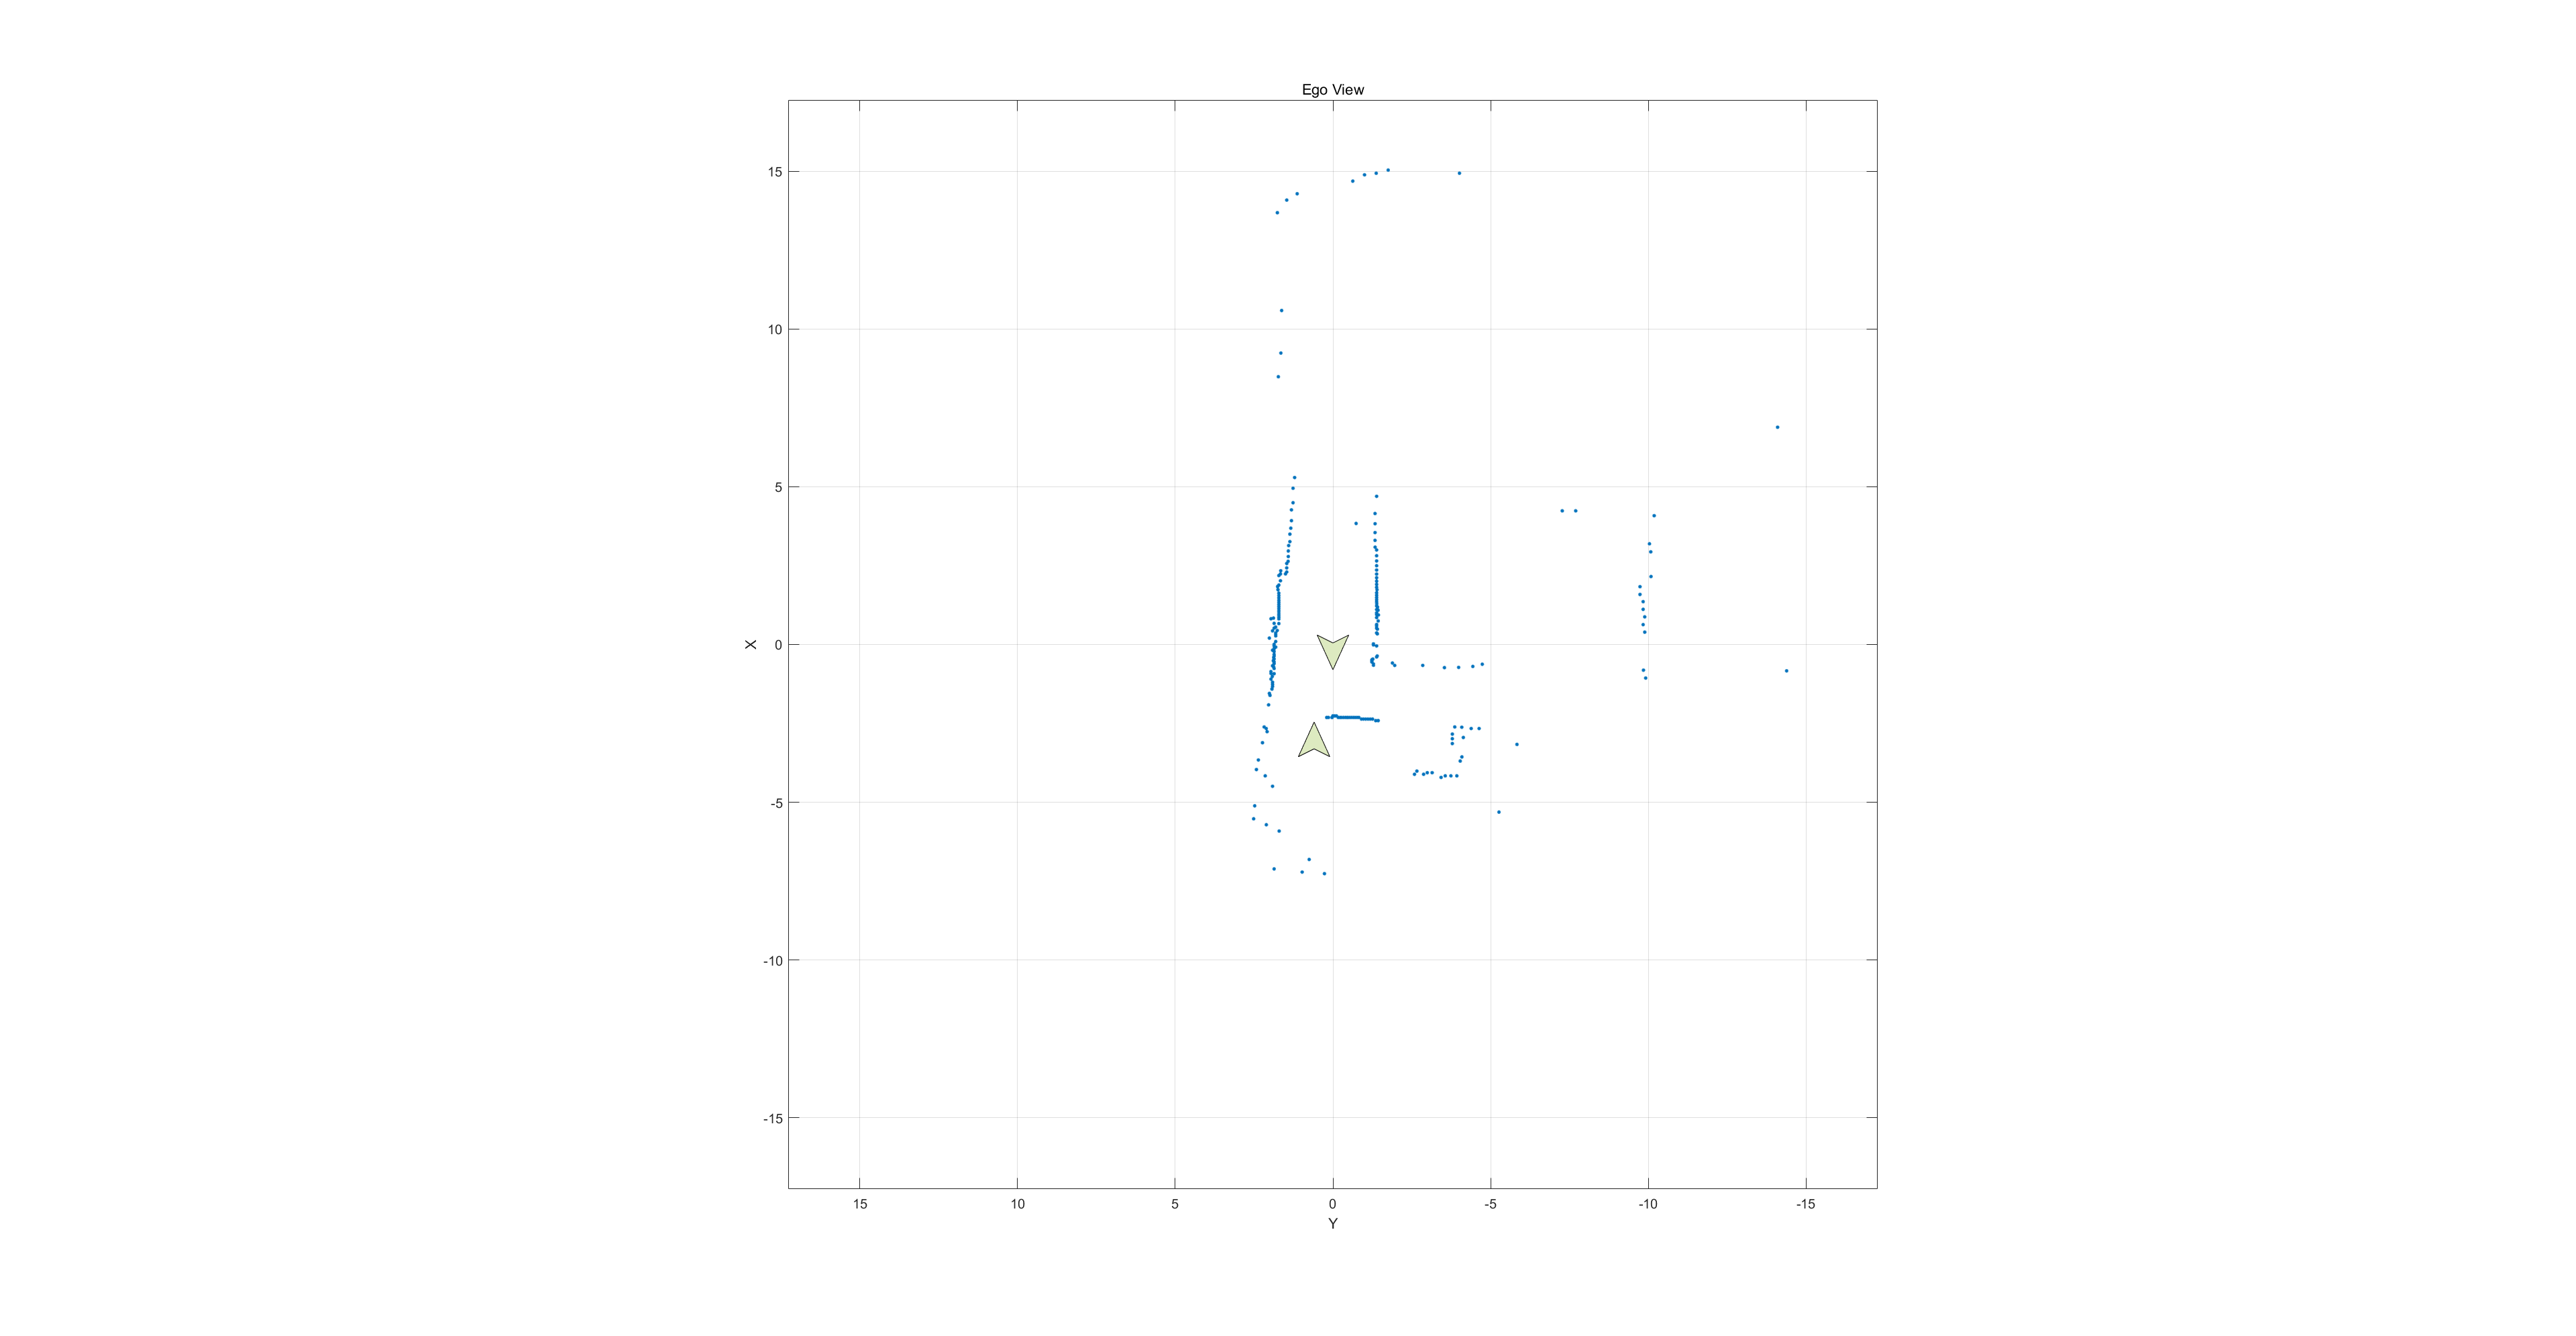

pose2 = goal;
helperPlotRobot(gca,pose2);

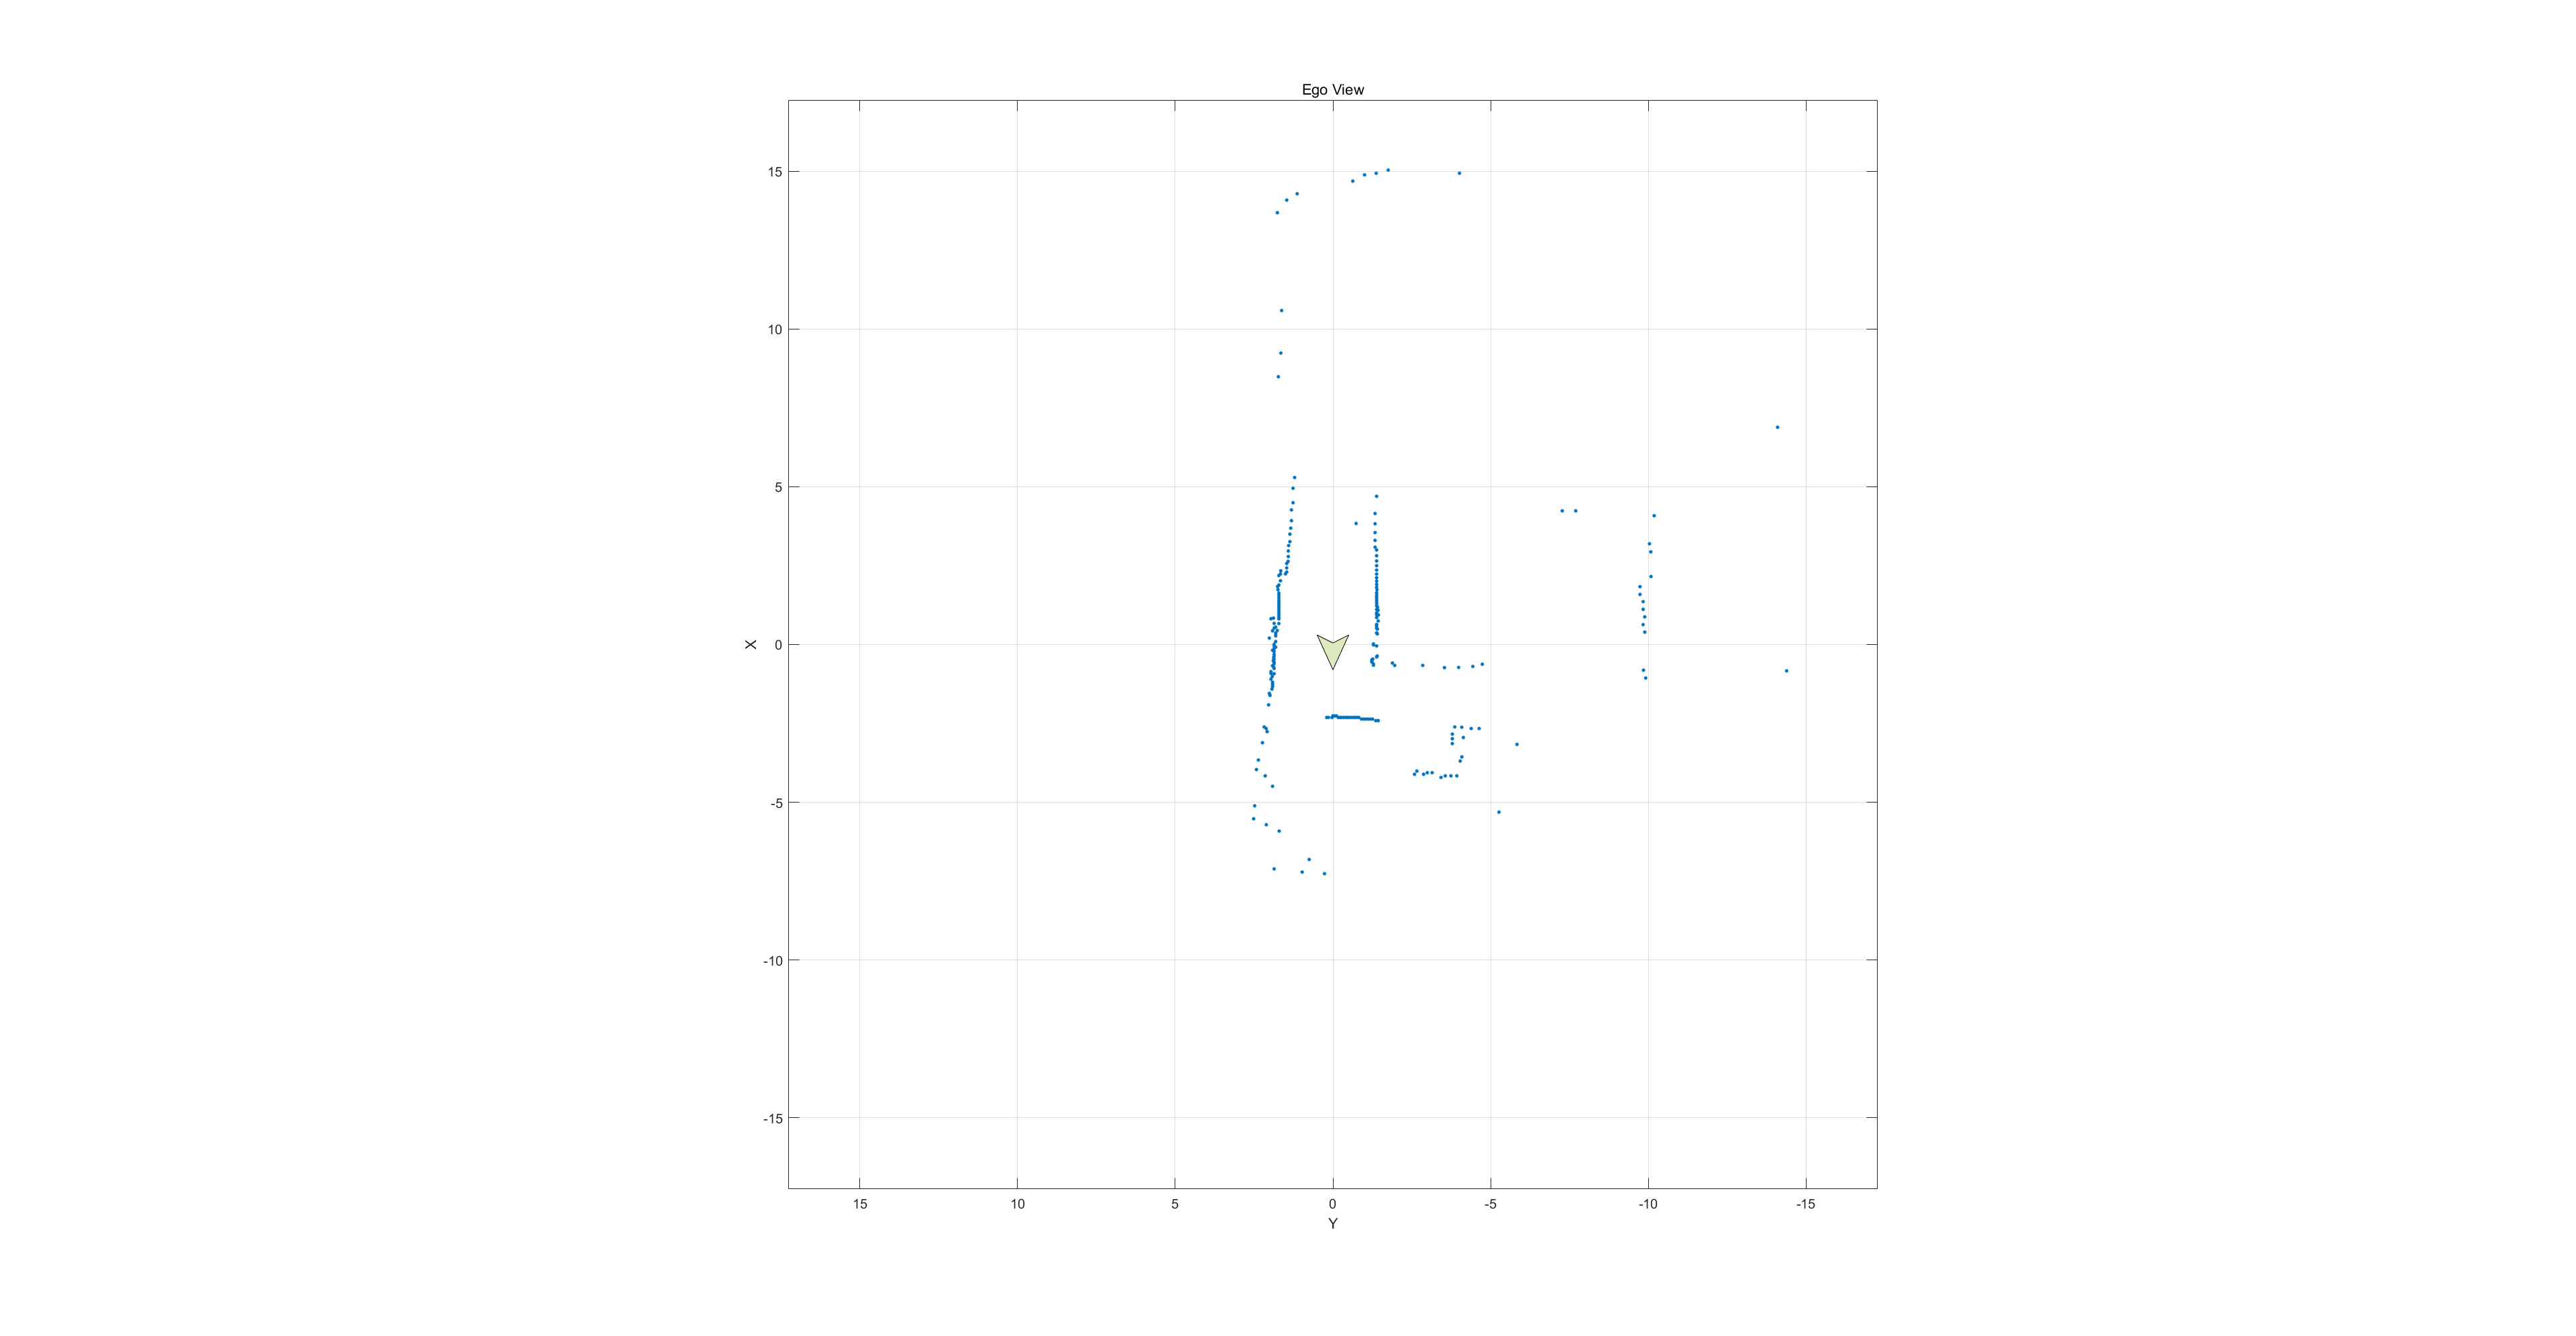


Vehiclepose2 = goal;


lidar = rangeSensor;
%lidar.HorizontalAngle = [-pi/2 pi/2];

[ranges2,angles2] = lidar(Vehiclepose2,map);


scantest2 = lidarScan(ranges2,angles2);
plot(scantest2)
title('Ego View')
helperPlotRobot(gca,[0 0 Vehiclepose(3)]);
%hold off

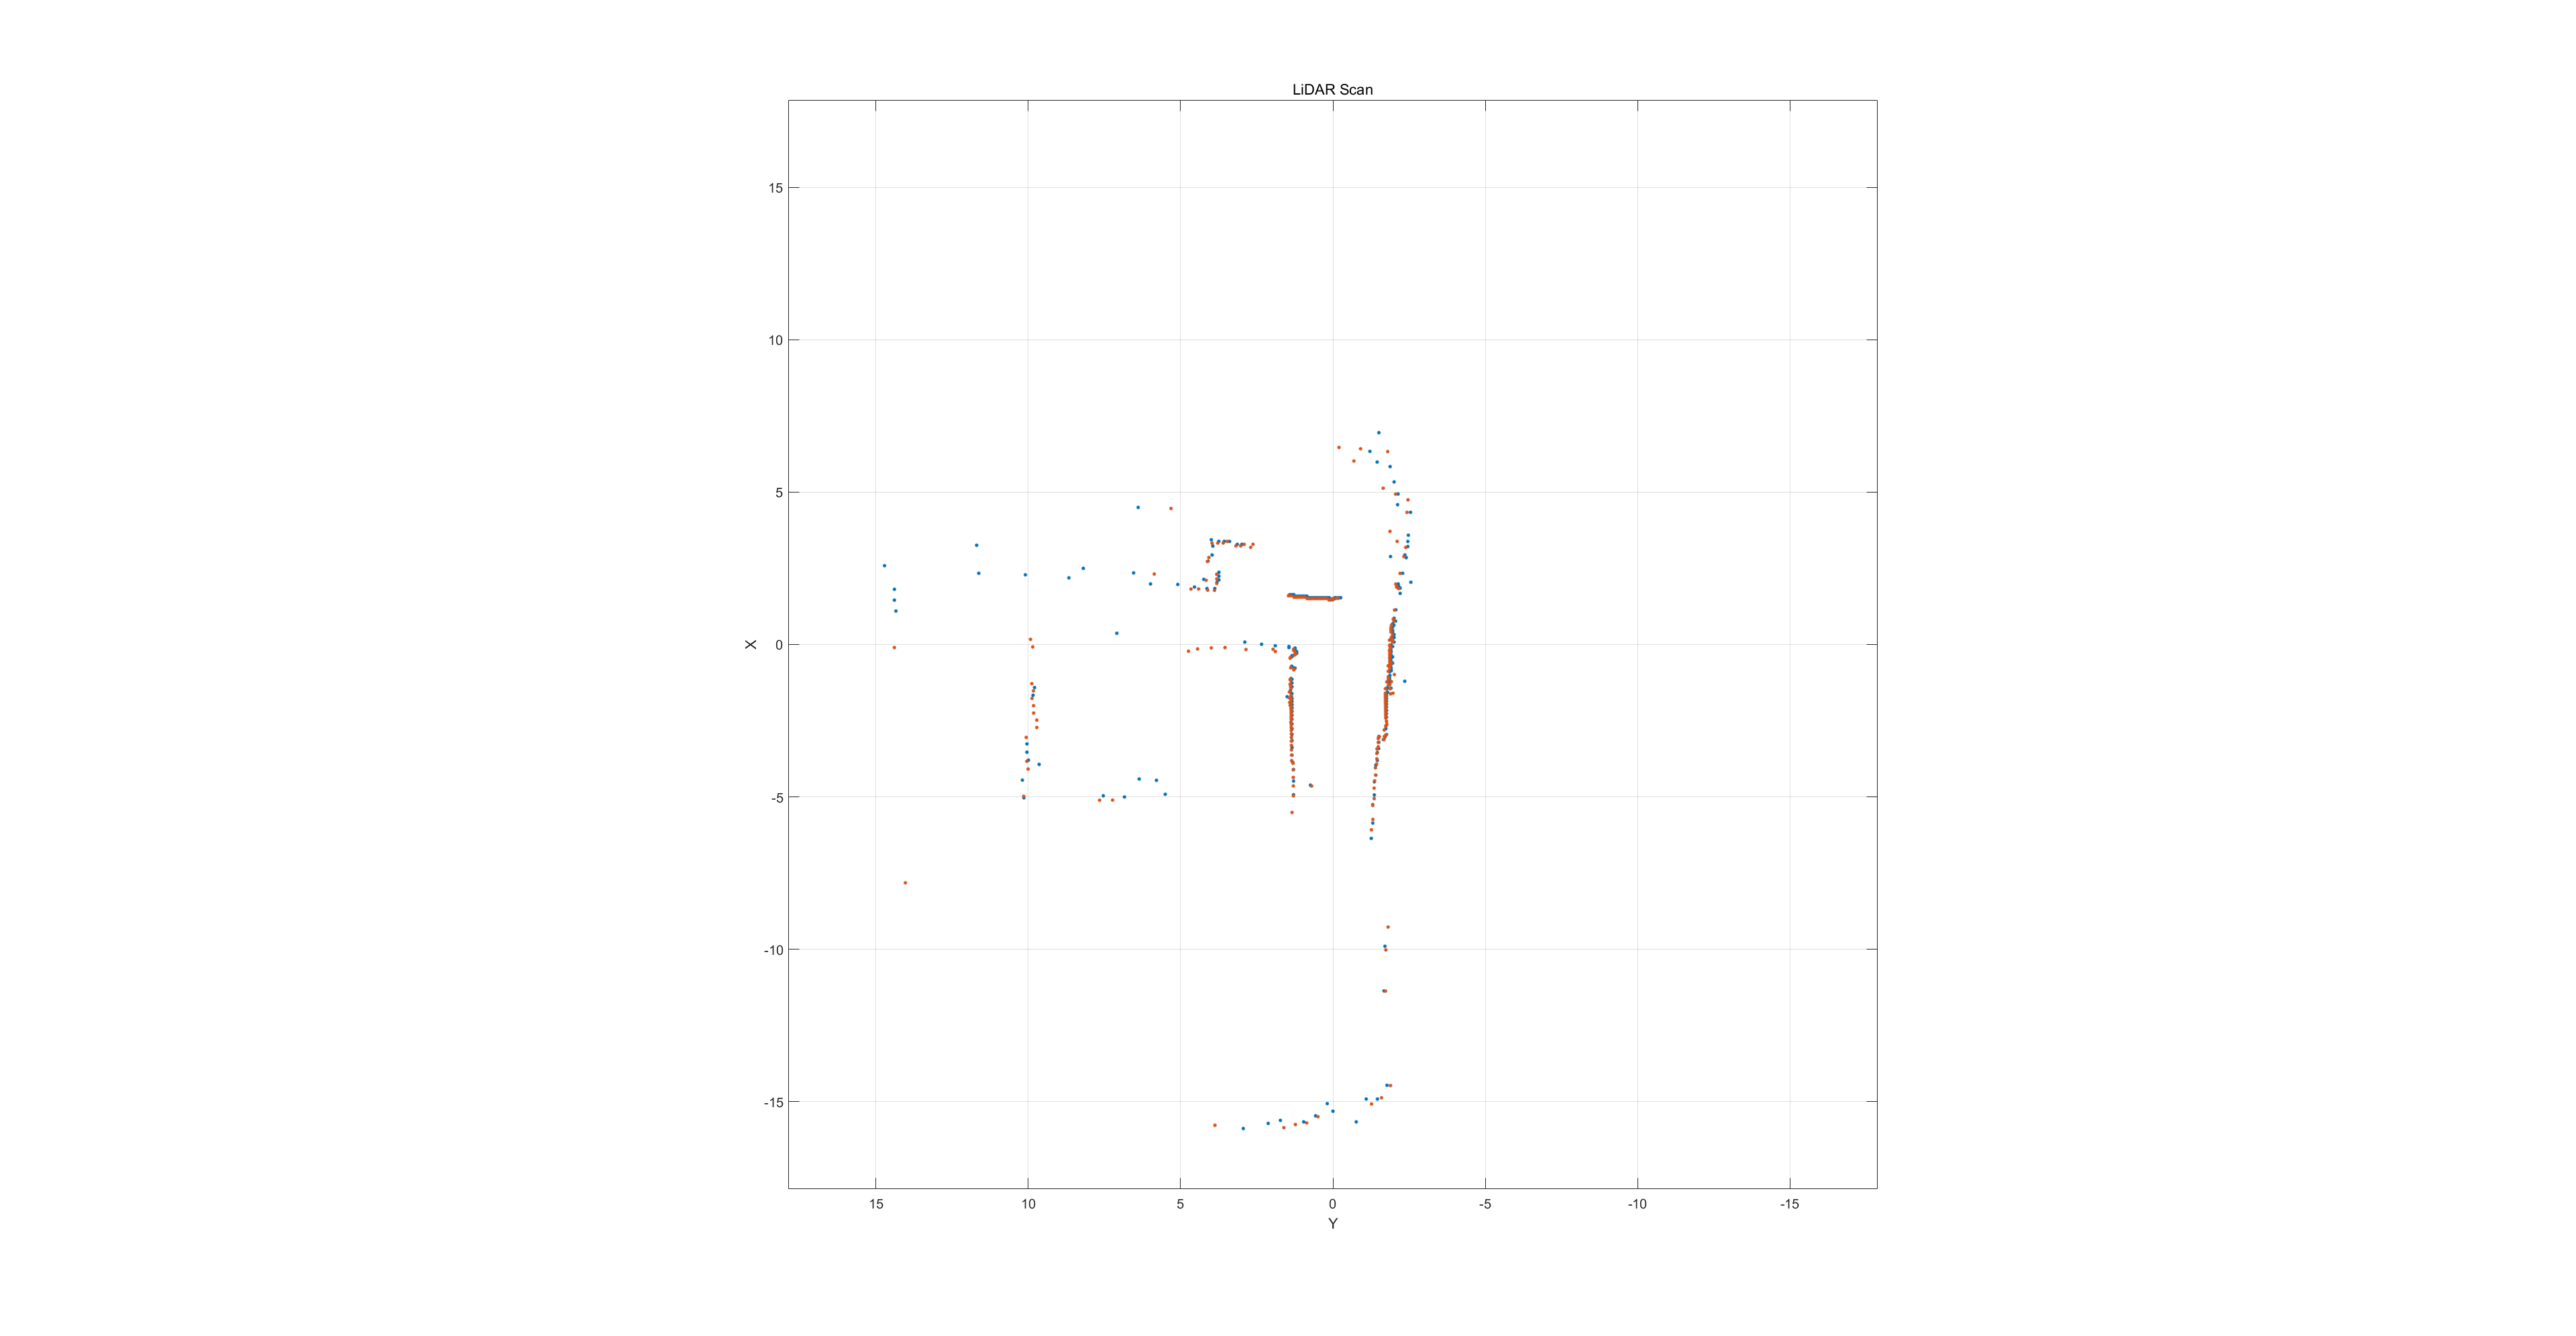

relPose = matchScansGrid(scantest,scantest2);

scan2Tformed = transformScan(scantest2,relPose);

plot(scantest)
hold on
plot(scan2Tformed)
hold off



%여기까지가 한거






## Define State Space

Specify the state space of the vehicle using a `stateSpaceDubins` object and specifying the state bounds. This object limits the sampled states to feasible Dubins curves for steering a vehicle within the state bounds. A turning radius of 0.4 meters allows for tight turns in this small environment.

bounds = [occGrid.XWorldLimits; occGrid.YWorldLimits; [-pi pi]];

ss = stateSpaceDubins(bounds); % ss = stateSpaceSE2; %으로 교체해보기
ss.MinTurningRadius = 0.4;

## Plan The Path

To plan a path, the RRT algorithm samples random states within the state space and attempts to connect a path. These states and connections need to be validated or excluded based on the map constraints. The vehicle must not collide with obstacles defined in the map.

Create a `validatorOccupancyMap` object with the specified state space. Set the `Map` property to the loaded `occupancyMap` object. Set a `ValdiationDistance` of 0.05 m. This validation distance discretizes the path connections and checks obstacles in the map based on this.

stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = occGrid;
stateValidator.ValidationDistance = 0.05;

Create the path planner and increase the max connection distance to connect more states. Set the maximum number of iterations for sampling states.

planner = plannerRRT(ss,stateValidator);
planner.MaxConnectionDistance = 2.0;
planner.MaxIterations = 30000;

Customize the `GoalReached` function. This example helper function checks if a feasible path reaches the goal within a set threshold. The function returns `true` when the goal has been reached, and the planner stops.

planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

Plan the path between the start and goal. Reset the random number generator for reproducible results.

rng default

[pthObj, solnInfo] = plan(planner,start,goal);

## Plot the Path

Show the occupancy map. Plot the search tree from the `solnInfo`. Interpolate and overlay the final path.

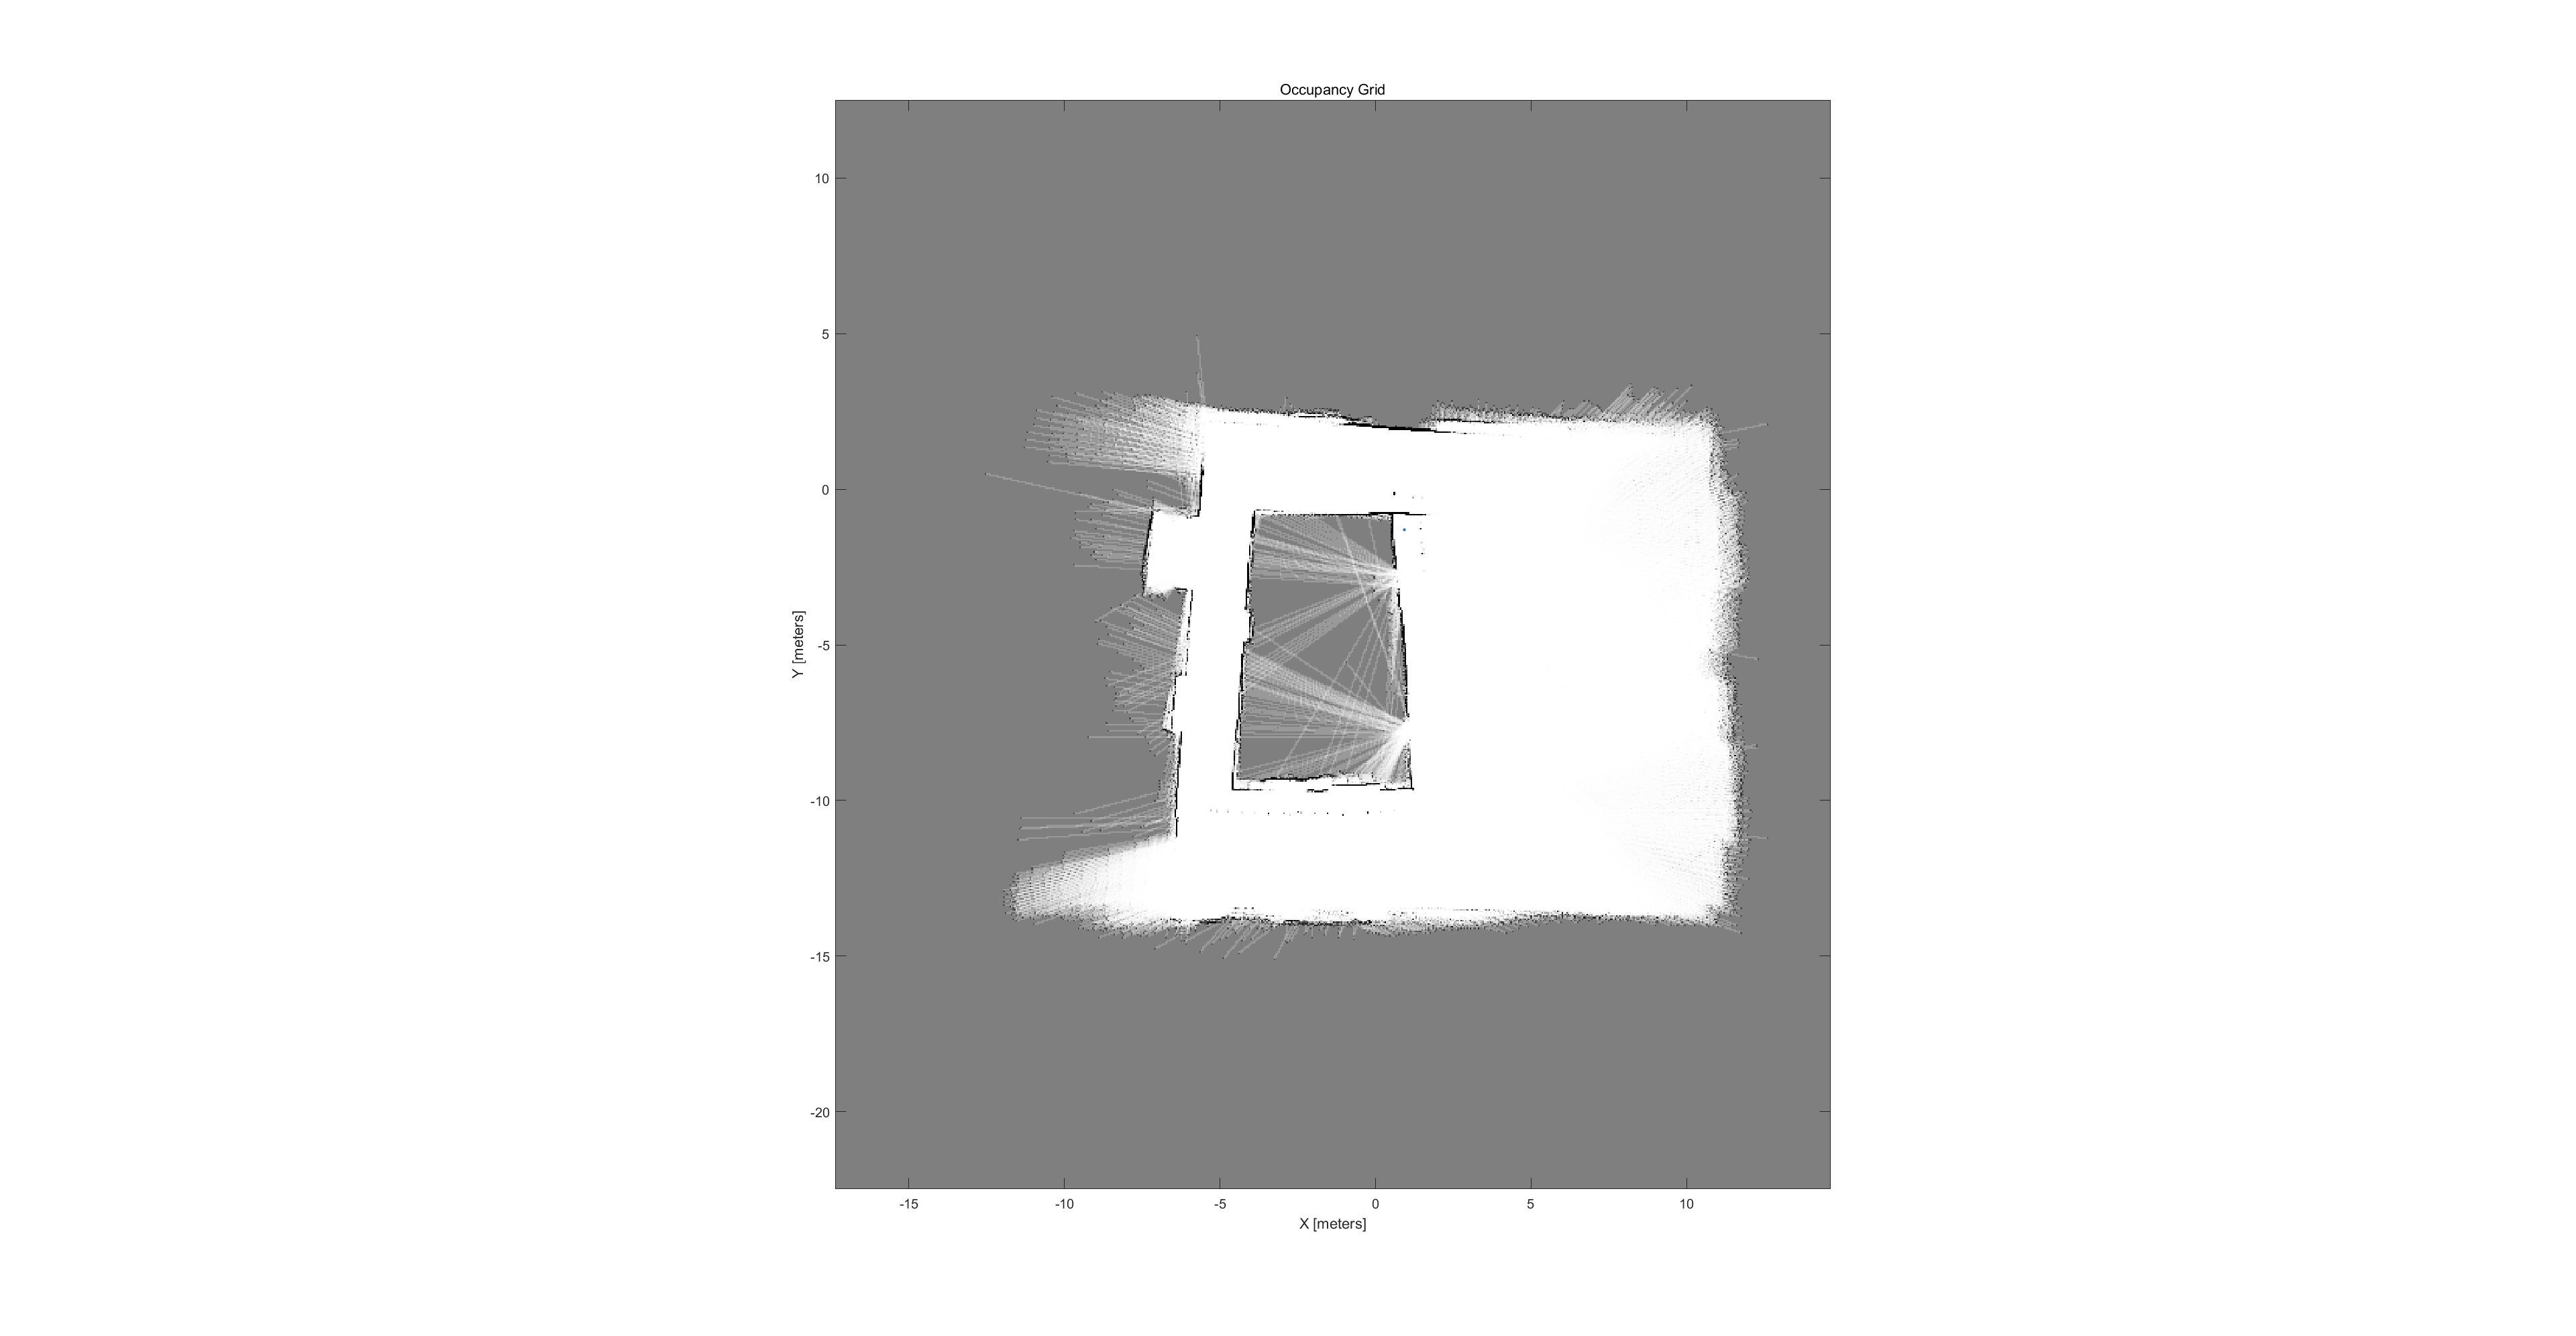

show(occGrid)
hold on

% Plot entire search tree.
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-');


% Interpolate and plot path.
interpolate(pthObj,300)

다음 사용 중 오류가 발생함: navPath/interpolate
Expected the path to have at least 2 states to interpolate, but only found 0.

plot(pthObj.States(:,1),pthObj.States(:,2),'r-','LineWidth',2)

% Show start and goal in grid map.
plot(start(1),start(2),'ro')
plot(goal(1),goal(2),'mo')
hold off